# **Polar Codes**

**Encoding and Successive List Decoding with Performance Analysis**

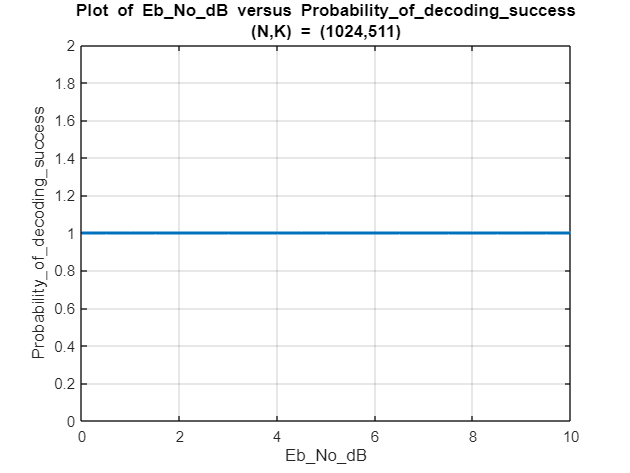

clearvars;
close all;
clc;

load('Reliability_Sequence.mat');
N = 1024;
n = log2(N);
A = 500;
CRC_Length = 11;
CRC_Polynomial = fliplr([1 1 1 0 0 0 1 0 0 0 0 1]);
K = A + CRC_Length;
Rate = A/N; 

global List_size;
List_size = 4;

Sequence = Reliability_Sequence(Reliability_Sequence <= N);
Frozen_bits = Sequence(1:N-K);

Nsim = 1000;
Eb_No_Range = 0:0.5:10;
Probability_of_decoding_success = zeros(1, length(Eb_No_Range));
Bit_Error_Rate = zeros(1, length(Eb_No_Range));
Block_Errors_Rate = zeros(1, length(Eb_No_Range));
Iteration_index = 1;

for Eb_No = Eb_No_Range
    Successful_Decoding = 0;
    Nsim_block_errors = 0; 
    Nsim_bit_errors = 0;

    for block = 1:Nsim
        message_sequence = randi([0 1], 1, A);
        [quotient, remainder] = gfdeconv([zeros(1, CRC_Length) fliplr(message_sequence)], CRC_Polynomial);
        CRC_padded_message = [message_sequence fliplr([remainder zeros(1, CRC_Length - length(remainder))])];
        message = zeros(1, N);
        message(Sequence(N-K+1:end)) = CRC_padded_message;
        
        code_word = Polar_Encoding(message, n);
        code_word = BPSK_AWGN_Introduction(code_word, Eb_No, A, N);

        global L;
        global ucap;
        global Path_matrix;
        global Node_states;

        L = zeros(List_size, n+1, N);
        L(:,1,:) = repmat(code_word, List_size, 1, 1);
        ucap = zeros(List_size, n+1, N);
        Node_states = zeros(1, 2*N-1);
        Path_matrix = Inf*ones(List_size, 1);
        Path_matrix(1) = 0;
        
        polar_decode(0, 0, n, Frozen_bits);
        message_cap_temp = squeeze(ucap(:,n+1, Sequence(N-K+1:end)));
        selected_code_word = 1;
        for count = 1:List_size
             [new_quotient, new_remainder] = gfdeconv(fliplr(message_cap_temp(count,:)), CRC_Polynomial);
             if (isequal(new_remainder, 0))
                 selected_code_word = count;
                 break;
             end
        end
        message_cap = message_cap_temp(selected_code_word, 1:A);
 
        Evident_errors = sum(message_sequence ~= message_cap);
        if(Evident_errors == 0)
            Successful_Decoding = Successful_Decoding + 1;
        else
            Nsim_bit_errors = Nsim_bit_errors + Evident_errors;
            Nsim_block_errors = Nsim_block_errors + 1;
        end
    end

    Probability_of_decoding_success(Iteration_index) = (1/Nsim)*Successful_Decoding;
    Bit_Error_Rate(Iteration_index) = Nsim_bit_errors/A/Nsim;
    Block_Errors_Rate(Iteration_index) = Nsim_block_errors/Nsim;
    Iteration_index = Iteration_index + 1;
end

plot(Eb_No_Range, Probability_of_decoding_success, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Probability\_of\_decoding\_success" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Probability\_of\_decoding\_success');
grid on;

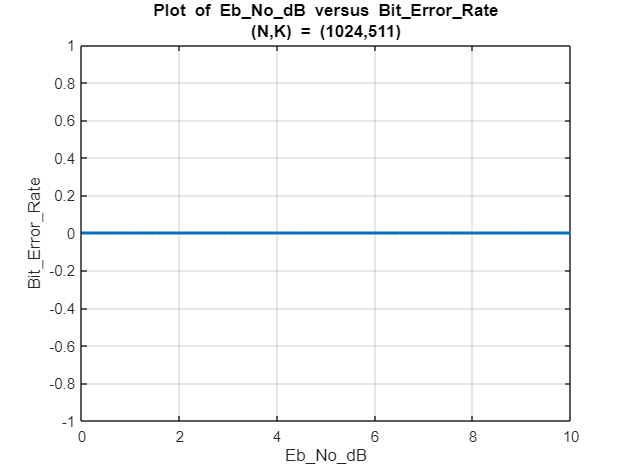

plot(Eb_No_Range, Bit_Error_Rate, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Bit\_Error\_Rate" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Bit\_Error\_Rate');
grid on;

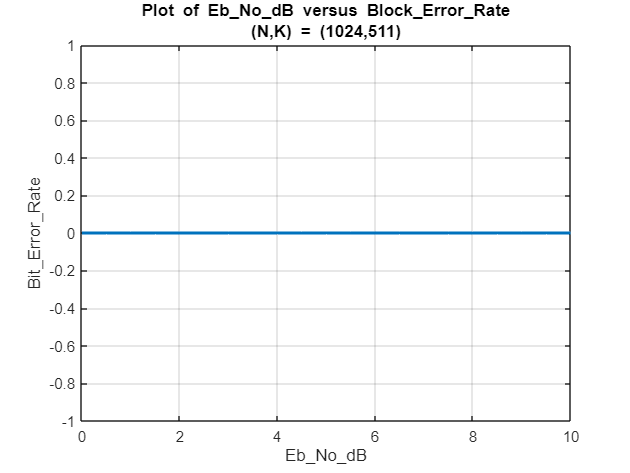

plot(Eb_No_Range, Block_Errors_Rate, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Block\_Error\_Rate" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Bit\_Error\_Rate');
grid on;

function code_word = Polar_Encoding(message, bit_length)
    Generator_Matrix = [1 0; 1 1];
    A = Generator_Matrix;
    B = Generator_Matrix;
    for count = 1:bit_length-1
       A = kron(A, B);
    end
    Generator_Matrix = A;
    code_word = mod(message*Generator_Matrix, 2);
end

function [y, pos] = mink(x, k)
    [xs, I] = sort(x);
    y = xs(1:k);
    pos = I(1:k);
end

function code_word = BPSK_AWGN_Introduction(code_word, Eb_No_dB, A, N)
    BPSK_modulated_code_word = 1 - 2*code_word;
    Eb_No = 10^(Eb_No_dB/10);
    Es_No = (A/N) * (Eb_No);
    sigma = sqrt(1 / Es_No);
    AWGN = sigma.*randn(1, N);
    
    code_word = BPSK_modulated_code_word + AWGN;
end

function polar_decode(Depth, Node, n, Frozen_bits)
    global L;
    global ucap;
    global Path_matrix;
    global List_size;
    global Node_states;

    f = @(r1,r2) (1-2*(r1<0)).*(1-2*(r2<0)).*min(abs(r1),abs(r2));
    g = @(r1,r2,c) r2+(1-2*c).*r1; 

    Node_Position = (2^Depth-1) + Node + 1;

    if Depth == n
       Node_states(Node_Position) = 3;
       Decision_matrix = squeeze(L(:, Depth+1, Node+1));   
       if any(Frozen_bits == (Node+1)) 
            ucap(:, Depth+1, Node+1) = 0; 
            Path_matrix = Path_matrix + abs(Decision_matrix).*(Decision_matrix < 0);
       else 
            Decisions = Decision_matrix < 0;
            Path_matrix_2 = [Path_matrix; Path_matrix + abs(Decision_matrix)];
            [Path_matrix, Position] = mink(Path_matrix_2, List_size);
            Surviving_Position = Position > List_size;
            Position(Surviving_Position) = Position(Surviving_Position) - List_size;
            Decisions = Decisions(Position);
            Decisions(Surviving_Position) = 1 - Decisions(Surviving_Position);
            L = L(Position, :, :);
            ucap = ucap(Position, :, :);
            ucap(:, Depth+1, Node+1) = Decisions;
       end 
       return;
    end

    temp = 2^(n-Depth);
    received_bits = squeeze(L(:, Depth+1, temp*Node+1:temp*(Node+1)));   

    if(Node_states(Node_Position) == 0)
        Node_states(Node_Position) = 1;
        a = received_bits(:, 1:temp/2);
        b = received_bits(:, temp/2+1:end);
        L(:, Depth+2, (temp/2)*(2*Node)+1:(temp/2)*((2*Node)+1)) = f(a,b);
        polar_decode(Depth+1, 2*Node, n, Frozen_bits);
    end

    received_bits = squeeze(L(:, Depth+1, temp*Node+1:temp*(Node+1))); 
    if(Node_states(Node_Position) == 1)
        Node_states(Node_Position) = 2;
        a = received_bits(:, 1:temp/2);
        b = received_bits(:, temp/2+1:end);
        Left_ucap = squeeze(ucap(:, Depth+2, (temp/2)*(2*Node)+1:(temp/2)*((2*Node)+1)));
        L(:, Depth+2, (temp/2)*(2*Node+1)+1:(temp/2)*((2*Node+1)+1)) = g(a, b, Left_ucap);
        polar_decode(Depth+1, 2*Node+1, n, Frozen_bits);
    end
    
    if(Node_states(Node_Position) == 2)
        Node_states(Node_Position) = 3;
        Left_ucap = squeeze(ucap(:, Depth+2, (temp/2)*(2*Node)+1:(temp/2)*((2*Node)+1))); 
        Right_ucap = squeeze(ucap(:, Depth+2, (temp/2)*(2*Node+1)+1:(temp/2)*((2*Node+1)+1)));
        ucap(:, Depth+1, temp*Node+1:temp*(Node+1)) = [mod(Left_ucap + Right_ucap, 2) Right_ucap]; 
    end
end
